# P2. Vehicle Lateral Dynamics

Vehicle Control Systems

Degree in Electronics, Robotics and Mechatronics Engineering

University of Malaga

Created by: David Rodríguez Martínez

Last updated: 28 September 2026

### Introduction and objectives

This file contains the coursework instructions and code blocks to complete. Extend the P1 race-car model with longitudinal and lateral dynamics while retaining the P1 longitudinal control functions.

This exercise requires the lateral equation of motion developed in Block 2 and both kinematic and dynamic bicycle models.

After completing this exercise, you should be able to:

- Implement the kinematic bicycle model, which is purely geometric without sliding, and the dynamic model using tyre forces and cornering stiffness. Together they extend P1's longitudinal model to capture lateral dynamics.

- Simulate a simplified FS Driverless event 2 skidpad: steady-state circular motion.

- Record vehicle yaw rate, lateral acceleration and slip angles as telemetry.

- Compare both models' results.

#### What you will implement

A) The kinematic model (function pasoCinematico)

B) The dynamic model (function pasoDinamico)

### Vehicle and road parameters

p = struct(); 

p.m    = 230;      % mass [kg]
p.g    = 9.81;     % gravity [m/s^2]
p.rho  = 1.225;    % air density [kg/m^3]
p.Cd   = 1.0;      % aerodynamic coefficient
p.Af   = 1.1;      % frontal area [m^2]
p.fr  = 0.022;    % rolling-resistance coefficient
p.Fx_drive_max = 2500;   % maximum driving force [N]
p.Fx_brake_max = 5000;   % maximum braking force [N]
p.theta = 0;      % road inclination [rad]

% Define the parameters needed to describe the vehicle's
% lateral dynamics here.
p.ld = 0.765; % [m] CG to front axle, longitudinal distance
p.lt = 0.765; % [m] CG to rear axle, longitudinal distance
p.lyd = 0.600; % [m] CG to front wheels, lateral distance
p.lyt = 0.600; % [m] CG to rear wheels, lateral distance
p.hcg = 0.230; % [m] centre-of-gravity height
% Wheel coordinates relative to the CG
% Order: DI, DD, TI, TD
p.xw = [p.ld,p.ld,-p.lt,-p.lt];
p.L = p.ld+p.lt; 
p.yw = [p.lyd, -p.lyd, p.lyt, -p.lyt];
p.td = p.lyd + p.lyt;
p.tt = p.td; 
p.Iz = 130; % [kg m^2] yaw inertia
p.Cad = 35000; % [N/rad] front cornering stiffness
p.Cat = 50000; % [N/rad] rear cornering stiffness --> understeering vehicle
p.Caw = [p.Cad/2, p.Cad/2, p.Cat/2, p.Cat/2];
p.nCa = 0.8; 
p.mu_t = 1.5; % rear tyre friction
p.mu_d = 0.95*p.mu_t; % front tyre friction
p.muw = [p.mu_d, p.mu_d, p.mu_t, p.mu_t];
% Lateral adhesion loss under excess traction demand
p.Kslip = 3; % Rear-wheel lateral-loss intensity
% Time dynamics of lateral loss and recovery
p.tau_slip_loss = 0.03; % loss time constant [s]
p.tau_slip_rec  = 0.50; % recovery time constant [s]
% Force allocation
p.Fzd0 = p.m*p.g*p.lt/p.L; % [N] initial front-axle vertical load
p.Fzt0 = p.m*p.g*p.ld/p.L; % [N] initial rear-axle vertical load
p.Fzw0 = [p.Fzd0/2, p.Fzd0/2, p.Fzt0/2, p.Fzt0/2]; % [N] initial vertical load per wheel
p.drive_w = [0, 0, 0.5, 0.5]; % Driving-force allocation during acceleration
p.brake_w = [0.3, 0.3, 0.2, 0.2]; % Longitudinal-force allocation during braking
p.kRoll = 0.5; % front share of roll moment (replace with a suspension model later)


### Vehicle model

Define the physics of both longitudinal and lateral vehicle motion here.

Important: this exercise defines the complete model that can serve as the basis of the individual project.

Given the current vehicle state, applied driving force and steering angle, calculate where the vehicle will be at the next time step.

Note: initialize the track geometry and controller first.

% Longitudinal and lateral dynamics integration

% u: control variable = [Fx; delta]
% z: vehicle state vector [X; Y; psi; vx; vy; r]
% X, Y = global CG position
% psi = heading / yaw angle
% vx, vy = chassis-frame velocities
% r = yaw rate

z0 = [0; -geom.R; 0; ctrl.v_skid; 0; 0]; % initial race-car state

function z_next = pasoCinematico(z, u, p, dt)
    Fx = u(1);
    delta = u(2);
    X = z(1); 
    Y = z(2);
    psi = z(3);
    vx = z(4);
    L = p.ld + p.lt;

    % Longitudinal dynamics (P1)
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2; 
    Rr = p.fr*p.m*p.g*cos(p.theta);
    Rg = p.m*p.g*sin(p.theta);
    ax = (Fx - Ra - sign(vx)*Rr - Rg)/p.m; % longitudinal equation of motion
    vx_next = max(vx + ax*dt,0);

    %% Lateral dynamics [kinematic]
    beta = atan((p.lt/L)*tan(delta)); % kinematic sideslip angle
    r = (vx/p.lt)*tan(beta);
    vy = vx*tan(beta);

    % transform to global coordinates
    X_next = X + (vx*cos(psi)-vy*sin(psi))*dt;
    Y_next = Y + (vx*sin(psi)+vy*cos(psi))*dt;
    psi_next = psi + r*dt; 

    z_next = [X_next; Y_next; psi_next; vx_next; vy; r]; % state vector at the next time step

end

function [z_next, tele] = pasoDinamico(z, u, p, dt, ax_prev, ay_prev, eta_prev)
    Fx = u(1);
    delta = u(2);
    X = z(1); 
    Y = z(2);
    psi = z(3);
    vx = z(4);
    vy = z(5);
    r = z(6);
    L = p.ld + p.lt;
    xw = p.xw;
    yw = p.yw;


    % vx_c = max(vx, 1.0); % corrected speed to avoid division by zero,
    % disabled now that the model uses atan2

    
    %% 1. Individual wheel kinematics

    delta_w = [delta, delta, 0, 0];

    % Wheel-centre velocities in chassis coordinates
    vxw = vx - r .* p.yw;
    vyw = vy + r .* p.xw;

    % Velocities projected into individual wheel coordinates
    vxw_local =  vxw .* cos(delta_w) + vyw .* sin(delta_w);
    vyw_local = -vxw .* sin(delta_w) + vyw .* cos(delta_w);

    % Individual slip angles
    alpha_w = delta_w-atan2(vyw_local, vxw_local);

    %% Define adhesion limits
    % Longitudinal transfer between axles
    dFzx = p.m*ax_prev*p.hcg/p.L;

    % Lateral transfer within each axle
    dFzyd = p.kRoll*p.m*ay_prev*p.hcg/p.td;
    dFzyt = (1-p.kRoll)*p.m*ay_prev*p.hcg/p.tt;

    % Order: DI, DD, TI, TD
    Fzw = p.Fzw0 + [-dFzx/2, -dFzx/2, dFzx/2, dFzx/2] + [-dFzyd,    dFzyd, -dFzyt,   dFzyt];
    % Longitudinal grip
    % Lateral forces per wheel
    Caw = p.Caw .* (Fzw ./ p.Fzw0).^p.nCa;
    Fyw = Caw .* alpha_w;

    % Longitudinal driving-force allocation per wheel
    if Fx >= 0
        Fxw_sol = Fx .* p.drive_w;
    else
        Fxw_sol = Fx .* p.brake_w;
    end

    % Per-wheel friction circle
    Fmax_w = p.muw .* Fzw; % Maximum force capacity per wheel
    Fres_w = hypot(Fxw_sol,Fyw); % Magnitude of requested resultant force
    lambda_w = min(ones(1,4),Fmax_w ./ max(Fres_w,eps)); % Saturation factor

    % Effective forces
    Fxw = lambda_w .* Fxw_sol;
    Fyw = lambda_w .* Fyw;

    
    %% Progressive lateral adhesion loss and recovery

    % Excess longitudinal demand relative to adhesion
    s_w = max(0, abs(Fxw_sol) ./ max(Fmax_w,eps) - 1);

    % Target lateral-capacity factor
    eta_obj = ones(1,4);

    % Additional loss is only triggered during driving
    if Fx > 0
        eta_obj(3:4) = 1 ./ (1 + p.Kslip .* s_w(3:4));
    end

    % Adhesion state inherited from the previous step
    eta_slip = eta_prev;

    % Rear-wheel time update
    for i = 3:4

        % Rapid loss or slow recovery
        if eta_obj(i) < eta_prev(i)
            tau = p.tau_slip_loss;
        else
            tau = p.tau_slip_rec;
        end

        % Stable exponential integration
        factor = 1 - exp(-dt/tau);

        eta_slip(i) = eta_prev(i) + factor * (eta_obj(i) - eta_prev(i));

    end

    % Bound the factor to its physically defined interval
    eta_slip = max(0,min(1,eta_slip));

    % Rear lateral-force reduction
    Fyw(3:4) = eta_slip(3:4) .* Fyw(3:4);

    % Chassis-frame components of lateral forces
    Fxw_chasis = Fxw .* cos(delta_w) - Fyw .* sin(delta_w);

    Fyw_chasis = Fxw .* sin(delta_w) + Fyw .* cos(delta_w);

    % Resultant forces and moment
    SumFx = sum(Fxw_chasis); % Total longitudinal force
    SumFy = sum(Fyw_chasis); % Total lateral force
    SumMz = sum(p.xw .* Fyw_chasis - p.yw .* Fxw_chasis); % Yaw moment about the CG

    % Telemetry: current-step data without changing forces or dynamics
    tele.alpha_w = alpha_w;
    tele.Fxw = Fxw;
    tele.Fyw = Fyw;
    tele.Fzw = Fzw;
    tele.Caw = Caw;
    tele.Mzw = p.xw .* Fyw_chasis - p.yw .* Fxw_chasis;
    tele.Mz_long = sum(p.xw .* (Fxw .* sin(delta_w)) - p.yw .* (Fxw .* cos(delta_w)));
    tele.Mz_lat = SumMz - tele.Mz_long;
    tele.lambda_w = lambda_w;
    tele.Fmax_w = Fmax_w;
    tele.s_w = s_w;
    tele.eta_slip = eta_slip;
    tele.eta_obj = eta_obj;

    % Longitudinal dynamics (P1)
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2; 
    Rr = p.fr*p.m*p.g*cos(p.theta);
    Rg = p.m*p.g*sin(p.theta);
    
    % equations of motion
    ax_fis = (SumFx - Ra - sign(vx)*Rr - Rg)/p.m;
    ay_fis = SumFy/p.m;
    ax  = ax_fis + vy*r; % retain centripetal coupling
    ay = ay_fis - vx*r; 
    dr = SumMz/p.Iz;   
    tele.ax = ax_fis;
    tele.ay = ay_fis;

    vx_next = max(vx + ax*dt,0);
    vy_next = vy + ay*dt; 
    r_next = r + dr*dt;
    X_next = X + (vx*cos(psi)-vy*sin(psi))*dt;
    Y_next = Y + (vx*sin(psi)+vy*cos(psi))*dt;
    psi_next = psi + r*dt; 

    z_next = [X_next; Y_next; psi_next; vx_next; vy_next; r_next]; 
end


### Speed controller

% PI speed controller with the same force saturation as P1
ctrl.v_skid = 14; % [m/s] originally 5 (18 km/h), changed to 8 to compare responses
ctrl.Kp = 800; 
ctrl.Ki = 200;

function [Fx, e_int] = controlLongitudinal(v_ref, vx, e_int, dt, ctrl, p)
    e = v_ref - vx;
    e_int = e_int + e*dt;

    Fx = ctrl.Kp*e + ctrl.Ki*e_int; % PI
    Fx = min(max(Fx, -p.Fx_brake_max), p.Fx_drive_max); % kinematic-model saturation
end


### Test-track geometry

Simulate the simplified skidpad: 2.5 laps around a constant-radius circle with a 15.25 m inner radius and a 3 m wide lane. Complete the trajectory as quickly as possible without leaving the lane. Only the second lap is timed.

%% SKIDPAD TEST SIMULATOR [DO NOT MODIFY]
geom.R_in = 15.25/2; % inner radius (blue cones) [m]
geom.R_out = geom.R_in + 3; % outer radius (yellow cones; 3 m lane) [m]
geom.R = (geom.R_in + geom.R_out)/2; % centreline radius [m]

function hist = simularE2(z0, p, ctrl, geom, dt, Tmax, modelo)
    N = round(Tmax/dt);  z = z0;  e_int = 0;
    ax_prev = 0;
    ay_prev = 0;
    eta_prev = ones(1,4);
    L = p.ld + p.lt;
    delta = atan(L/geom.R); 
    hist.t=zeros(1,N); hist.X=zeros(1,N); hist.Y=zeros(1,N); hist.psi=zeros(1,N);
    hist.vx=zeros(1,N); hist.vy=zeros(1,N); hist.r=zeros(1,N);
    hist.af=zeros(1,N); hist.ar=zeros(1,N);
    % New telemetry for the four-wheel dynamic model only
    es4R = strcmp(func2str(modelo), 'pasoDinamico');
    if es4R
        hist.alpha_w = zeros(N,4);
        hist.Fxw = zeros(N,4);
        hist.Fyw = zeros(N,4);
        hist.Fzw = zeros(N,4);
        hist.Mzw = zeros(N,4);
        hist.Mz_long = zeros(1,N);
        hist.Mz_lat = zeros(1,N);
        hist.lambda_w = zeros(N,4);
        hist.Fmax_w = zeros(N,4);
        hist.s_w = zeros(N,4);
        hist.eta_slip = ones(N,4);
    end
    for k = 1:N
        [Fx, e_int] = controlLongitudinal(ctrl.v_skid, z(4), e_int, dt, ctrl, p);
        u = [Fx; delta];
        vx_c = max(z(4), 1.0);
        hist.af(k) = delta - (z(5) + p.ld*z(6))/vx_c;
        hist.ar(k) =       - (z(5) - p.lt*z(6))/vx_c;
        if es4R
            [z, tele] = modelo(z, u, p, dt, ax_prev, ay_prev, eta_prev);
            hist.alpha_w(k,:) = tele.alpha_w;
            hist.Fxw(k,:) = tele.Fxw;
            hist.Fyw(k,:) = tele.Fyw;
            hist.Fzw(k,:) = tele.Fzw;
            hist.Mzw(k,:) = tele.Mzw;
            hist.Mz_long(k) = tele.Mz_long;
            hist.Mz_lat(k) = tele.Mz_lat;
            hist.lambda_w(k,:) = tele.lambda_w;
            hist.Fmax_w(k,:) = tele.Fmax_w;
            hist.s_w(k,:) = tele.s_w;
            hist.eta_slip(k,:) = tele.eta_slip;
            eta_prev = tele.eta_slip;
            ax_prev = tele.ax;
            ay_prev = tele.ay;

        else
            z = modelo(z, u, p, dt);
        end
        hist.t(k)=(k-1)*dt; hist.X(k)=z(1); hist.Y(k)=z(2); hist.psi(k)=z(3);
        hist.vx(k)=z(4); hist.vy(k)=z(5); hist.r(k)=z(6);
    end
    th = unwrap(atan2(hist.Y, hist.X));
    nV = floor((th - th(1))/(2*pi));                  
    hist.tVueltas = zeros(1, max(0, max(nV)));        
    for n = 1:numel(hist.tVueltas)
        hist.tVueltas(n) = hist.t(find(nV >= n, 1));
    end
    rad = hypot(hist.X, hist.Y);
    hist.fueraCarril = any(rad < geom.R_in | rad > geom.R_out);
end

function informarVueltas(nombre, hist)
    dur = diff([0, hist.tVueltas]);
    if numel(dur) >= 2
        fprintf('   %s: second lap = %.2f s', nombre, dur(2));
    else
        fprintf('   %s: does not complete 2 laps within Tmax', nombre);
    end
    if hist.fueraCarril, fprintf('   (leaves the track!)'); end
    fprintf('\n');
end

### Simulation

dt   = 0.002; 
Tmax = 2.5*2*pi*geom.R/ctrl.v_skid; % approximately 2.5 laps; the second is timed

histCin = simularE2(z0, p, ctrl, geom, dt, Tmax, @pasoCinematico);
histDin = simularE2(z0, p, ctrl, geom, dt, Tmax, @pasoDinamico);

idx = round(2*numel(histCin.t)/3):numel(histCin.t);
Rcin = mean(histCin.vx(idx)./max(histCin.r(idx),1e-6));
Rdin = mean(histDin.vx(idx)./max(histDin.r(idx),1e-6));

### Results

Expected response: the kinematic model follows a circle of about 9 m radius from geometry alone; the dynamic model follows a slightly larger radius because of understeer. Small slip angles and both axles' cornering stiffness determine this mild understeer. These descriptive values are retained from the original exercise.

fprintf('Ackermann R = %.2f m  (delta = %.2f deg)\n', geom.R, atan((p.ld+p.lt)/geom.R)*180/pi);

Ackermann R = 9.12 m  (delta = 9.52 deg)


fprintf('Measured radius — kinematic: %.2f m | dynamic: %.2f m\n', Rcin, Rdin);

Radio medido — cinemático: 9.13 m | dinámico: 14.23 m


fprintf('Understeer: dynamic radius is %.1f%% larger.\n', 100*(Rdin-Rcin)/Rcin);

Subviraje: el dinámico traza 55.9% más radio.


fprintf('Timing (FS rule: the second lap of each circle is timed):\n');

Tiempos (regla FS: se cronometra la 2ª vuelta de cada círculo):


informarVueltas('kinematic', histCin);

   cinemático: 2ª vuelta = 4.11 s


informarVueltas('dynamic', histDin);

   dinámico  : no completa 2 vueltas en Tmax   (¡sale del carril!)


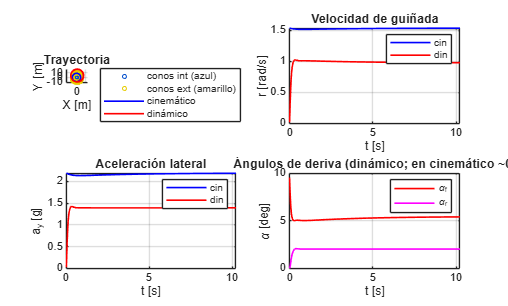

figure('Name','L2 · Skidpad','Color','w');

subplot(2,2,1); hold on; axis equal; grid on;  
  th = linspace(0,2*pi,200);
  plot(geom.R_in*cos(th), geom.R_in*sin(th), 'o','Color',[0 .3 .8],'MarkerSize',3);
  plot(geom.R_out*cos(th),geom.R_out*sin(th),'o','Color',[.9 .8 0],'MarkerSize',3);
  plot(histCin.X, histCin.Y, 'b-','LineWidth',1.2);
  plot(histDin.X, histDin.Y, 'r-','LineWidth',1.2);
  legend('inner cones (blue)','outer cones (yellow)','kinematic','dynamic','Location','bestoutside');
  title('Trajectory'); xlabel('X [m]'); ylabel('Y [m]');

subplot(2,2,2);   
  plot(histCin.t,histCin.r,'b', histDin.t,histDin.r,'r','LineWidth',1.2);
  ylabel('r [rad/s]'); xlabel('t [s]'); grid on; legend('cin','din');
  title('Yaw rate');

subplot(2,2,3);   
  plot(histCin.t, histCin.vx.*histCin.r/9.81,'b', ...
       histDin.t, histDin.vx.*histDin.r/9.81,'r','LineWidth',1.2);
  ylabel('a_y [g]'); xlabel('t [s]'); grid on; legend('cin','din');
  title('Lateral acceleration');

subplot(2,2,4);   
  plot(histDin.t, histDin.af*180/pi,'r', histDin.t, histDin.ar*180/pi,'m','LineWidth',1.2);
  ylabel('\alpha [deg]'); xlabel('t [s]'); grid on; legend('\alpha_f','\alpha_r');
  title('Slip angles (dynamic; approximately zero in kinematic)');

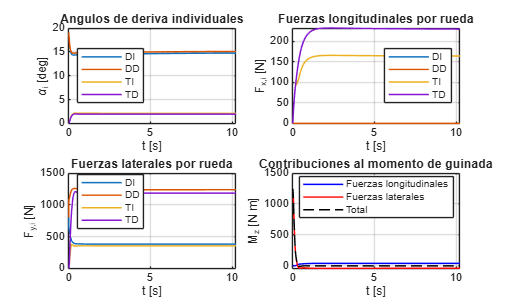


%% NEW FIGURE: four-wheel dynamic-model telemetry
% Wheel order: DI, DD, TI, TD. Original simulation is unchanged.
figure('Name','Four-wheel model - telemetry','Color','w');
nombres = {'DI','DD','TI','TD'};

subplot(2,2,1);
plot(histDin.t, rad2deg(histDin.alpha_w), 'LineWidth',1.1);
grid on; xlabel('t [s]'); ylabel('\alpha_i [deg]');
title('Individual slip angles'); legend(nombres,'Location','best');

subplot(2,2,2);
plot(histDin.t, histDin.Fxw, 'LineWidth',1.1);
grid on; xlabel('t [s]'); ylabel('F_{x,i} [N]');
title('Longitudinal forces per wheel'); legend(nombres,'Location','best');

subplot(2,2,3);
plot(histDin.t, histDin.Fyw, 'LineWidth',1.1);
grid on; xlabel('t [s]'); ylabel('F_{y,i} [N]');
title('Lateral forces per wheel'); legend(nombres,'Location','best');

subplot(2,2,4);
plot(histDin.t, histDin.Mz_long, 'b', ...
     histDin.t, histDin.Mz_lat, 'r', ...
     histDin.t, histDin.Mz_long + histDin.Mz_lat, 'k--', 'LineWidth',1.1);
grid on; xlabel('t [s]'); ylabel('M_z [N m]');
title('Yaw-moment contributions');
legend('Longitudinal forces','Lateral forces','Total','Location','best');

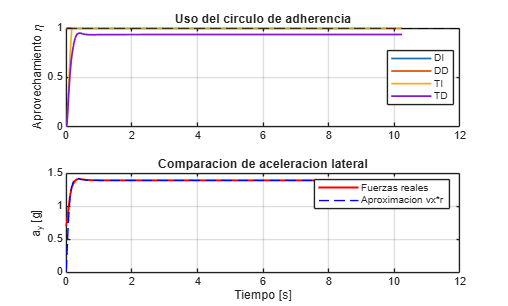

%% Friction-circle check

t = histDin.t(:);
Fx = histDin.Fxw;
Fy = histDin.Fyw;
Fz = histDin.Fzw;

% Adhesion utilization per wheel
Fmax = Fz .* p.muw;
eta = hypot(Fx, Fy) ./ Fmax;

% Lateral acceleration from forces
delta = atan((p.ld + p.lt)/geom.R);
delta_w = [delta, delta, 0, 0];

Fy_chasis = Fx.*sin(delta_w) + Fy.*cos(delta_w);
ay_real = sum(Fy_chasis, 2)/(p.m*p.g);

% Plots
figure('Color','w');

subplot(2,1,1)
plot(t, eta, 'LineWidth',1.3)
yline(1,'k--','Adhesion limit');
grid on;
ylabel('Utilization \eta');
legend('DI','DD','TI','TD','Location','best');
title('Friction-circle utilization');

subplot(2,1,2)
plot(t, ay_real, 'r','LineWidth',1.5)
hold on;
plot(t, histDin.vx(:).*histDin.r(:)/p.g, 'b--');
grid on;
xlabel('Time [s]');
ylabel('a_y [g]');
legend('Actual forces','Approximation vx*r');
title('Lateral-acceleration comparison');


% Numerical check
fprintf('Maximum utilization per wheel:\n');

Aprovechamiento maximo por rueda:


disp(max(eta,[],1));

    1.0000    1.0000    1.0000    0.9482




fprintf('Maximum lateral acceleration: %.3f g\n', ...
    max(abs(ay_real)));

Aceleracion lateral maxima: 1.409 g


fprintf('\n--- FOUR-WHEEL MODEL SUMMARY ---\n');


--- Resumen modelo 4 ruedas ---


fprintf('Final speed: %.2f m/s\n', histDin.vx(end));

Velocidad final: 13.95 m/s


fprintf('Final yaw rate: %.3f rad/s\n', histDin.r(end));

Guiñada final: 0.977 rad/s


fprintf('Max |slip angle| per wheel [deg]:');

Max |deriva| por rueda [deg]: 

fprintf('%.2f ', max(abs(rad2deg(histDin.alpha_w)),[],1));

19.04 19.04 2.17 1.98 

fprintf('\nMax |Fx| per wheel [N]:');


Max |Fx| por rueda [N]: 

fprintf('%.1f ', max(abs(histDin.Fxw),[],1));

0.0 0.0 165.6 232.3 

fprintf('\nMax |Fy| per wheel [N]:');


Max |Fy| por rueda [N]: 

fprintf('%.1f ', max(abs(histDin.Fyw),[],1));

803.8 1258.1 386.8 1206.8 

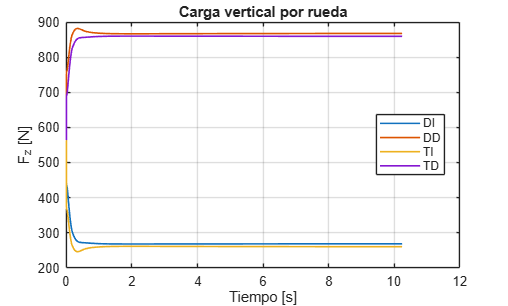

fprintf('\n');
%% Results: load transfer and cornering stiffness
t = histDin.t(:);
Fz = histDin.Fzw;
nombres = {'DI','DD','TI','TD'};

% Stiffness used at each step
Ca = p.Caw .* (Fz ./ p.Fzw0).^p.nCa;

% Effective forces and adhesion capacity
Fres = hypot(histDin.Fxw, histDin.Fyw);
Fmax = Fz .* p.muw;
eta = Fres ./ max(Fmax,eps);

figure
plot(t, Fz, 'LineWidth',1.2);
grid on;
xlabel('Time [s]'); ylabel('F_z [N]');
title('Vertical wheel load');
legend(nombres,'Location','best');

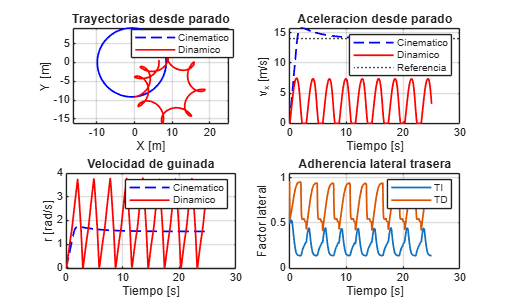


%% SKIDPAD FROM REST

% Initial state at zero speed
z0Skid = [0; -geom.R; 0; 0; 0; 0];

% Longer duration to include acceleration
TmaxSkid = 25;

% Run both models with the same reference
histSkid0Cin = simularE2( ...
    z0Skid, p, ctrl, geom, dt, TmaxSkid, @pasoCinematico);

histSkid0Din = simularE2( ...
    z0Skid, p, ctrl, geom, dt, TmaxSkid, @pasoDinamico);

% Results display
figure('Name','Skidpad from rest','Color','w');

subplot(2,2,1)
plot(histSkid0Cin.X,histSkid0Cin.Y,'b--','LineWidth',1.3);
hold on;
plot(histSkid0Din.X,histSkid0Din.Y,'r','LineWidth',1.3);
axis equal; grid on;
xlabel('X [m]'); ylabel('Y [m]');
title('Trajectories from rest');
legend('Kinematic','Dynamic','Location','best');

subplot(2,2,2)
plot(histSkid0Cin.t,histSkid0Cin.vx,'b--', ...
    histSkid0Din.t,histSkid0Din.vx,'r','LineWidth',1.3);
yline(ctrl.v_skid,'k:');
grid on;
xlabel('Time [s]'); ylabel('v_x [m/s]');
title('Acceleration from rest');
legend('Kinematic','Dynamic','Reference');

subplot(2,2,3)
plot(histSkid0Cin.t,histSkid0Cin.r,'b--', ...
    histSkid0Din.t,histSkid0Din.r,'r','LineWidth',1.3);
grid on;
xlabel('Time [s]'); ylabel('r [rad/s]');
title('Yaw rate');
legend('Kinematic','Dynamic');

subplot(2,2,4)
plot(histSkid0Din.t,histSkid0Din.eta_slip(:,3:4),...
    'LineWidth',1.3);
grid on;
xlabel('Time [s]');
ylabel('Lateral factor');
ylim([0 1.05]);
title('Rear lateral adhesion');
legend('TI','TD');


fprintf('\n--- SKIDPAD FROM REST ---\n');


--- SKIDPAD DESDE PARADO ---


fprintf('Maximum lateral reduction: %.1f %%\n', ...
    100*(1-min(histSkid0Din.eta_slip(:,3:4),[],'all')));

Reduccion lateral maxima: 86.2 %


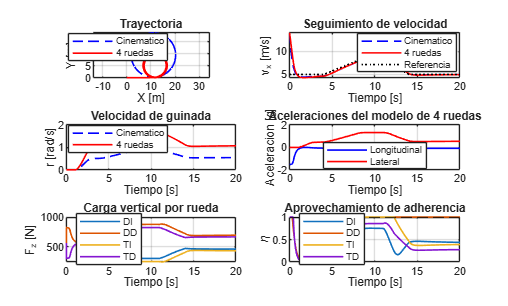

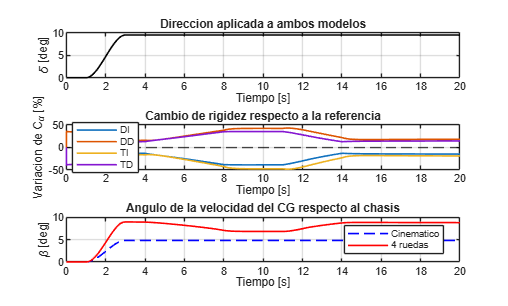


--- Curva: aceleracion y frenada ---
Carga minima por rueda [N]:
  304.3969  564.0750  245.2188  302.3912

Maximo aprovechamiento por rueda:
    1.0000    1.0000    1.0000    1.0000

Tiempo con alguna rueda saturada: 88.7 %
Error maximo de equilibrio vertical: 0.000e+00 N


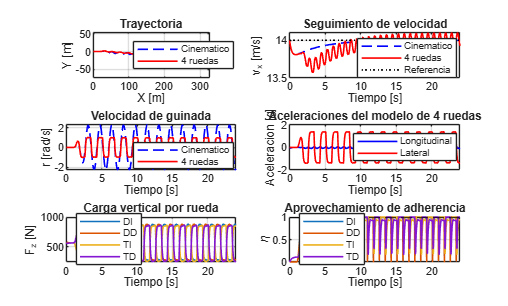

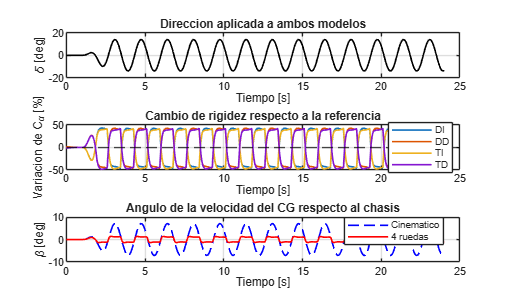


--- Eslalon ---
Carga minima por rueda [N]:
  253.4568  253.4403  248.1875  243.8460

Maximo aprovechamiento por rueda:
    1.0000    1.0000    1.0000    1.0000

Tiempo con alguna rueda saturada: 87.3 %
Error maximo de equilibrio vertical: 0.000e+00 N



%% New tests: acceleration/braking in a corner and slalom
dtEnsayo = 0.002;

% Case 2: cornering with acceleration and braking
caso2.nombre = 'Corner: acceleration and braking';
caso2.T = 20;
caso2.v0 = 14;

% Steering equivalent to nominal skidpad radius
caso2.delta = atan(p.L/9.125);

% Case 4: slalom
caso4.nombre = 'Slalom';
caso4.T = 24;
caso4.v0 = 14;
caso4.amplitud = deg2rad(14);
caso4.frecuencia = 0.6; % Hz

casos = {caso2, caso4};

for j = 1:numel(casos)
    caso = casos{j};

    cin = simularManiobra(p, ctrl, dtEnsayo, caso, j, false);
    din = simularManiobra(p, ctrl, dtEnsayo, caso, j, true);

    mostrarManiobra(cin, din, p, caso.nombre);

    if j == 1
        histCurvaCin = cin;
        histCurvaDin = din;
    else
        histEslalonCin = cin;
        histEslalonDin = din;
    end
end

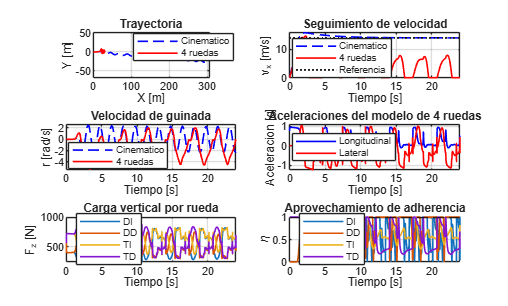

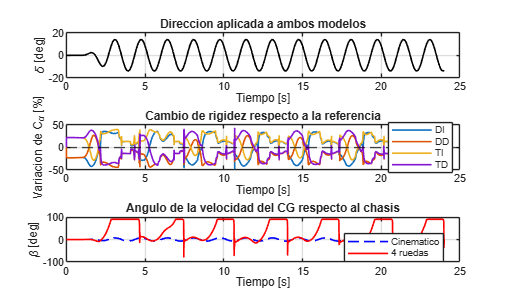


--- Eslalon desde parado ---
Carga minima por rueda [N]:
  249.8709  271.4997  368.3012  299.2440

Maximo aprovechamiento por rueda:
    1.0000    1.0000    1.0000    1.0000

Tiempo con alguna rueda saturada: 100.0 %
Error maximo de equilibrio vertical: 4.547e-13 N



%% SLALOM FROM REST

% New slalom configuration
casoEslalon0 = caso4;

casoEslalon0.nombre = 'Slalom from rest';
casoEslalon0.v0 = 0;
casoEslalon0.vobjetivo = 14;
casoEslalon0.T = 24;

% Run both models
histEslalon0Cin = simularManiobra( ...
    p, ctrl, dtEnsayo, casoEslalon0, 2, false);

histEslalon0Din = simularManiobra( ...
    p, ctrl, dtEnsayo, casoEslalon0, 2, true);

% Original comparison plots
mostrarManiobra( ...
    histEslalon0Cin, histEslalon0Din, ...
    p, casoEslalon0.nombre);


%% SLALOM ANIMATION - CONTROLLED PLAYBACK

% Slalom-from-rest history
h = histEslalon0Din;

% Geometry
a = p.ld;
b = p.lt;
W = p.td;

% Playback configuration
fps = 25;
nFrames = 250;
indices = unique(round(linspace(1,length(h.t),nFrames)));

% Create a separate window
fig = figure('Name','Slalom animation', ...
    'NumberTitle','off', ...
    'Color','w', ...
    'WindowStyle','normal', ...
    'Visible','on');

ax = axes('Parent',fig);
hold(ax,'on');
grid(ax,'on');
axis(ax,'equal');

xlabel(ax,'X [m]');
ylabel(ax,'Y [m]');

% Complete trajectory as reference
X = h.z(:,1);
Y = h.z(:,2);

margen = 5;
xlim(ax,[min(X)-margen,max(X)+margen]);
ylim(ax,[min(Y)-margen,max(Y)+margen]);

% Travelled trajectory
tray = plot(ax,NaN,NaN,'b-', ...
    'LineWidth',1.5);

% Vehicle chassis
veh = patch(ax,NaN,NaN,[0.2 0.5 0.9], ...
    'FaceAlpha',0.5, ...
    'EdgeColor','b', ...
    'LineWidth',1.5);

% Chassis steering indicator
dir = plot(ax,NaN,NaN,'r-', ...
    'LineWidth',2);

% Vehicle corners relative to the CG
esquinas = [a a -b -b;
            W/2 -W/2 -W/2 W/2];

%% Playback

for j = 1:length(indices)

    if ~isgraphics(fig)
        break
    end

    k = indices(j);

    % Vehicle position and orientation
    x = h.z(k,1);
    y = h.z(k,2);
    psi = h.z(k,3);

    % Rotation matrix
    R = [cos(psi), -sin(psi);
         sin(psi),  cos(psi)];

    % Corner transformation
    puntos = R*esquinas + [x;y];

    % Update chassis
    set(veh,'XData',puntos(1,:), ...
            'YData',puntos(2,:));

    % Update orientation
    set(dir, ...
        'XData',[x,x+a*cos(psi)], ...
        'YData',[y,y+a*sin(psi)]);

    % Update trajectory
    set(tray,'XData',X(1:k),'YData',Y(1:k));

    % Time information
    title(ax,sprintf( ...
        'Slalom | t = %.2f s | v = %.1f km/h', ...
        h.t(k), ...
        3.6*hypot(h.z(k,4),h.z(k,5))));

    % Show and hold the frame
    drawnow;
    pause(1/fps);

end

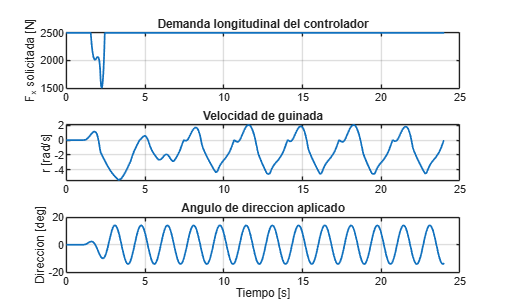

 
% Additional diagnostics
figure('Name','Slalom from rest - diagnostics',...
    'Color','w');

subplot(3,1,1)
plot(histEslalon0Din.t,histEslalon0Din.Fx_cmd,...
    'LineWidth',1.3);
grid on;
ylabel('Requested F_x [N]');
title('Controller longitudinal demand');

subplot(3,1,2)
plot(histEslalon0Din.t,histEslalon0Din.z(:,6),...
    'LineWidth',1.3);
grid on;
ylabel('r [rad/s]');
title('Yaw rate');

subplot(3,1,3)
plot(histEslalon0Din.t, ...
    rad2deg(histEslalon0Din.delta), ...
    'LineWidth',1.3);
grid on;
xlabel('Time [s]');
ylabel('Steering [deg]');
title('Applied steering angle');

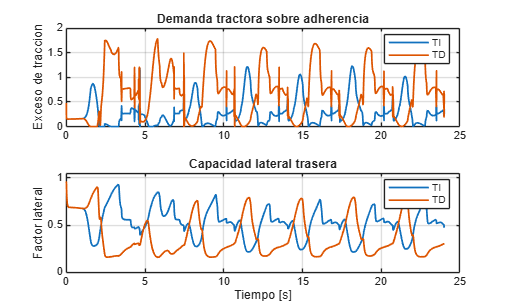




%% Lateral loss in the slalom-from-rest test

figure('Name','Slalom - rear traction loss','Color','w');

subplot(2,1,1)
plot(histEslalon0Din.t, ...
    histEslalon0Din.s_w(:,3:4), ...
    'LineWidth',1.3);
grid on;
ylabel('Excess traction demand');
legend('TI','TD');
title('Driving demand relative to adhesion');

subplot(2,1,2)
plot(histEslalon0Din.t, ...
    histEslalon0Din.eta_slip(:,3:4), ...
    'LineWidth',1.3);
grid on;
xlabel('Time [s]');
ylabel('Lateral factor');
ylim([0 1.05]);
legend('TI','TD');
title('Rear lateral capacity');


fprintf('\n--- SLALOM FROM REST ---\n');


--- ESLALON DESDE PARADO ---


fprintf('Maximum lateral reduction: %.1f %%\n', ...
    100*(1-min(histEslalon0Din.eta_slip(:,3:4),[],'all')));

Reduccion lateral maxima: 84.1 %



%% TEST 4: Full-demand launch from rest

% Configuration
dtArr = 0.002;
TArr = 8;
NArr = round(TArr/dtArr);

FxArr = p.Fx_drive_max;  % Maximum driving demand: 2500 N
deltaArr = deg2rad(15); % Constant steering

% Comparison without/with additional lateral loss
Kvalores = [0, 3];
nCasos = numel(Kvalores);

arranque = cell(1,nCasos);

for j = 1:nCasos

    pTest = p;
    pTest.Kslip = Kvalores(j);

    % Initial state: stationary vehicle
    z = [0; 0; 0; 0; 0; 0];

    ax_prev = 0;
    ay_prev = 0;
    eta_prev = ones(1,4);

    % Telemetry initialization
    h.t = (0:NArr-1)'*dtArr;
    h.z = zeros(NArr,6);
    h.Fxw = zeros(NArr,4);
    h.Fyw = zeros(NArr,4);
    h.Fmax_w = zeros(NArr,4);
    h.s_w = zeros(NArr,4);
    h.eta_slip = ones(NArr,4);
    h.ax = zeros(NArr,1);
    h.ay = zeros(NArr,1);

    % Constant demand without PI controller
    u = [FxArr; deltaArr];

    for k = 1:NArr

        h.z(k,:) = z.';

        [z_next, tele] = pasoDinamico(z, u, pTest, dtArr, ax_prev, ay_prev, eta_prev);

        h.Fxw(k,:) = tele.Fxw;
        h.Fyw(k,:) = tele.Fyw;
        h.Fmax_w(k,:) = tele.Fmax_w;
        h.s_w(k,:) = tele.s_w;
        h.eta_slip(k,:) = tele.eta_slip;
        eta_prev = tele.eta_slip;
        h.ax(k) = tele.ax;
        h.ay(k) = tele.ay;

        ax_prev = tele.ax;
        ay_prev = tele.ay;

        z = z_next;
    end

    arranque{j} = h;
end

%% Results comparison

% Retrieve results from both simulations
h0 = arranque{1};  % Without additional slip-related loss
h3 = arranque{2};  % With additional slip-related loss

% Check that states have been stored
disp(fieldnames(h0))

    {'t'       }
    {'z'       }
    {'vref'    }
    {'delta'   }
    {'Fx_cmd'  }
    {'Fzw'     }
    {'Caw'     }
    {'eta'     }
    {'ax'      }
    {'ay'      }
    {'lambda_w'}
    {'s_w'     }
    {'eta_slip'}
    {'Fxw'     }
    {'Fyw'     }
    {'Fmax_w'  }



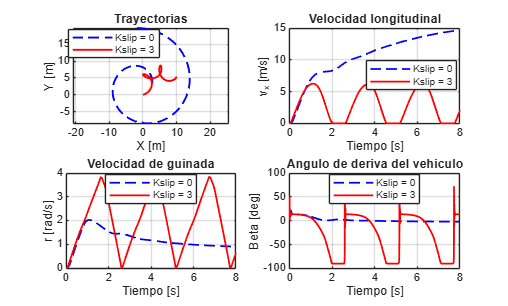


assert(isfield(h0,'z'), ...
    'Missing field z. Run the Test 4 loop first.');

assert(isfield(h3,'z'), ...
    'Missing field z in the second simulation.');


figure('Name','Test 4 - launch with steering',...
       'Color','w');

subplot(2,2,1)
plot(h0.z(:,1),h0.z(:,2),'b--','LineWidth',1.4);
hold on;
plot(h3.z(:,1),h3.z(:,2),'r','LineWidth',1.4);
axis equal; grid on;
xlabel('X [m]'); ylabel('Y [m]');
title('Trajectories');
legend('Kslip = 0','Kslip = 3','Location','best');

subplot(2,2,2)
plot(h0.t,h0.z(:,4),'b--', ...
     h3.t,h3.z(:,4),'r','LineWidth',1.3);
grid on;
xlabel('Time [s]'); ylabel('v_x [m/s]');
title('Longitudinal speed');
legend('Kslip = 0','Kslip = 3','Location','best');

subplot(2,2,3)
plot(h0.t,h0.z(:,6),'b--', ...
     h3.t,h3.z(:,6),'r','LineWidth',1.3);
grid on;
xlabel('Time [s]'); ylabel('r [rad/s]');
title('Yaw rate');
legend('Kslip = 0','Kslip = 3','Location','best');

subplot(2,2,4)
plot(h0.t,rad2deg(atan2(h0.z(:,5),h0.z(:,4))), ...
     'b--','LineWidth',1.3);
hold on;
plot(h3.t,rad2deg(atan2(h3.z(:,5),h3.z(:,4))), ...
     'r','LineWidth',1.3);
grid on;
xlabel('Time [s]'); ylabel('Beta [deg]');
title('Vehicle sideslip angle');
legend('Kslip = 0','Kslip = 3','Location','best');

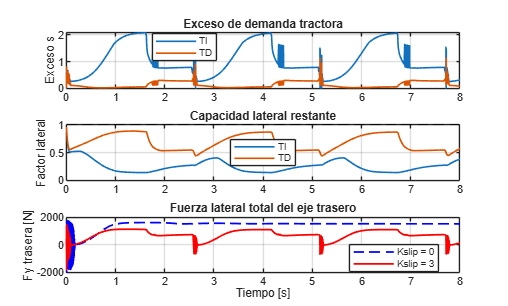



%% Lateral-loss mechanism diagnostics

figure('Name','Test 4 - rear adhesion loss',...
       'Color','w');

subplot(3,1,1)
plot(h3.t,h3.s_w(:,3:4),'LineWidth',1.2);
grid on;
ylabel('Excess s');
title('Excess driving demand');
legend('TI','TD','Location','best');

subplot(3,1,2)
plot(h3.t,h3.eta_slip(:,3:4),'LineWidth',1.2);
hold on;
yline(1,'k--');
grid on;
ylabel('Lateral factor');
title('Remaining lateral capacity');
legend('TI','TD','Location','best');

subplot(3,1,3)
plot(h0.t,sum(h0.Fyw(:,3:4),2),'b--', ...
     h3.t,sum(h3.Fyw(:,3:4),2),'r', ...
     'LineWidth',1.3);
grid on;
xlabel('Time [s]');
ylabel('Rear Fy [N]');
title('Total rear-axle lateral force');
legend('Kslip = 0','Kslip = 3','Location','best');


%% Numerical summary

fprintf('\n--- TEST 4: LAUNCH WITH STEERING ---\n');


--- ENSAYO 4: ARRANQUE CON DIRECCION ---



for j = 1:nCasos
    h = arranque{j};

    fprintf('\nKslip = %.1f\n',Kvalores(j));
    fprintf('Final speed: %.2f m/s\n',h.z(end,4));
    fprintf('Final yaw rate: %.3f rad/s\n',h.z(end,6));

    beta = atan2(h.z(:,5),h.z(:,4));
    fprintf('Max |beta|: %.2f deg\n', ...
        max(abs(rad2deg(beta))));

    fprintf('Maximum lateral reduction: %.1f %%\n', ...
        100*(1-min(h.eta_slip(:,3:4),[],'all')));

    fprintf('Time with additional lateral loss: %.1f %%\n', ...
        100*mean(any(h.eta_slip(:,3:4)<1-1e-6,2)));
end


Kslip = 0.0


Velocidad final: 14.70 m/s


Guiñada final: 0.898 rad/s


Max |beta|: 50.59 deg


Reduccion lateral maxima: 0.0 %


Tiempo con perdida lateral adicional: 0.0 %



Kslip = 3.0


Velocidad final: 2.05 m/s


Guiñada final: 0.645 rad/s


Max |beta|: 90.00 deg


Reduccion lateral maxima: 86.2 %


Tiempo con perdida lateral adicional: 100.0 %


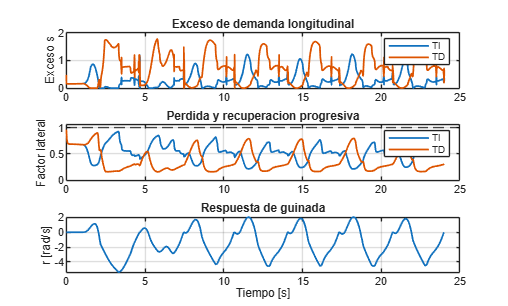


%% V6 - Rear adhesion over time

h = histEslalon0Din;

figure('Name','V6 - adhesion recovery','Color','w');

subplot(3,1,1)
plot(h.t,h.s_w(:,3:4),'LineWidth',1.3);
grid on;
ylabel('Excess s');
title('Excess longitudinal demand');
legend('TI','TD');

subplot(3,1,2)
plot(h.t,h.eta_slip(:,3:4),'LineWidth',1.3);
hold on;
yline(1,'k--');
grid on;
ylim([0 1.05]);
ylabel('Lateral factor');
title('Progressive loss and recovery');
legend('TI','TD');

subplot(3,1,3)
plot(h.t,h.z(:,6),'LineWidth',1.3);
grid on;
xlabel('Time [s]');
ylabel('r [rad/s]');
title('Yaw response');


% Recovery diagnostics
eta_min = min(h.eta_slip(:,3:4),[],2);

fprintf('\n--- V6: ADHESION RECOVERY ---\n');


--- V6: RECUPERACION DE ADHERENCIA ---


fprintf('Maximum lateral reduction: %.1f %%\n', ...
    100*(1-min(eta_min)));

Reduccion lateral maxima: 84.1 %



fprintf('Time with lateral loss > 10%%: %.2f s\n', ...
    sum(eta_min < 0.9)*dtEnsayo);

Tiempo con perdida lateral > 10%: 23.99 s




function hist = simularManiobra(p, ctrl, dt, caso, tipo, dinamico)

N = round(caso.T/dt);
z = [0; 0; 0; caso.v0; 0; 0];

e_int = 0;
ax_prev = 0;
ay_prev = 0;
eta_prev = ones(1,4);

hist.t = (0:N-1)'*dt;
hist.z = zeros(N,6);
hist.vref = zeros(N,1);
hist.delta = zeros(N,1);
hist.Fx_cmd = zeros(N,1);

if dinamico
    hist.Fzw = zeros(N,4);
    hist.Caw = zeros(N,4);
    hist.eta = zeros(N,4);
    hist.ax = zeros(N,1);
    hist.ay = zeros(N,1);
    hist.lambda_w = zeros(N,4);
    hist.s_w = zeros(N,4);
    hist.eta_slip = ones(N,4);
end

for k = 1:N
    t = hist.t(k);

    if tipo == 1
        % Corner entry between 1 and 3 s
        s = min(max((t-1)/2,0),1);
        entrada = s^2*(3-2*s);

        delta = caso.delta*entrada;

        % 0-4 s: 5 m/s
        % 4-8 s: progressively increase to 8 m/s
        % 8-11 s: 8 m/s
        % 11-14 s: progressively decrease to 5 m/s
        % 14-20 s: 5 m/s
        subida = min(max((t-4)/4,0),1);
        bajada = min(max((t-11)/3,0),1);

        vref = 5 + 3*subida - 3*bajada;

    else
        % Smooth slalom entry between 1 and 3 s
        s = min(max((t-1)/2,0),1);
        entrada = s^2*(3-2*s);

        delta = entrada*caso.amplitud * sin(2*pi*caso.frecuencia*(t-1));

        
        % Speed reference independent of initial speed
        if isfield(caso,'vobjetivo')
            vref = caso.vobjetivo;
        else
            vref = caso.v0;
        end

    end

    [Fx, e_int] = controlLongitudinal(vref, z(4), e_int, dt, ctrl, p);

    u = [Fx; delta];

    % States and inputs at the start of the step
    hist.z(k,:) = z.';
    hist.vref(k) = vref;
    hist.delta(k) = delta;
    hist.Fx_cmd(k) = Fx;

    if dinamico
        [z_next, tele] = pasoDinamico(z, u, p, dt, ax_prev, ay_prev, eta_prev);

        hist.Fzw(k,:) = tele.Fzw;
        hist.Caw(k,:) = tele.Caw;

        hist.eta(k,:) = hypot(tele.Fxw,tele.Fyw)./ max(tele.Fmax_w,eps);

        hist.ax(k) = tele.ax;
        hist.ay(k) = tele.ay;
        hist.lambda_w(k,:) = tele.lambda_w;
        hist.s_w(k,:) = tele.s_w;
        hist.eta_slip(k,:) = tele.eta_slip;
        eta_prev = tele.eta_slip;

        ax_prev = tele.ax;
        ay_prev = tele.ay;

    else
        z_next = pasoCinematico(z, u, p, dt);
    end

    z = z_next;
end
end
function mostrarManiobra(cin, din, p, nombre)

t = din.t;
ruedas = {'DI','DD','TI','TD'};

figure('Name',nombre,'Color','w');

subplot(3,2,1)
plot(cin.z(:,1),cin.z(:,2),'b--', ...
    din.z(:,1),din.z(:,2),'r','LineWidth',1.2);
axis equal; grid on;
xlabel('X [m]'); ylabel('Y [m]');
title('Trajectory');
legend('Kinematic','Four wheels','Location','best');

subplot(3,2,2)
plot(t,cin.z(:,4),'b--', ...
    t,din.z(:,4),'r', ...
    t,din.vref,'k:','LineWidth',1.2);
grid on;
xlabel('Time [s]'); ylabel('v_x [m/s]');
title('Speed tracking');
legend('Kinematic','Four wheels','Reference','Location','best');

subplot(3,2,3)
plot(t,cin.z(:,6),'b--', ...
    t,din.z(:,6),'r','LineWidth',1.2);
grid on;
xlabel('Time [s]'); ylabel('r [rad/s]');
title('Yaw rate');
legend('Kinematic','Four wheels','Location','best');

subplot(3,2,4)
plot(t,din.ax/p.g,'b', ...
    t,din.ay/p.g,'r','LineWidth',1.2);
grid on;
xlabel('Time [s]'); ylabel('Acceleration [g]');
title('Four-wheel-model accelerations');
legend('Longitudinal','Lateral','Location','best');

subplot(3,2,5)
plot(t,din.Fzw,'LineWidth',1.2);
grid on;
xlabel('Time [s]'); ylabel('F_z [N]');
title('Vertical wheel load');
legend(ruedas,'Location','best');

subplot(3,2,6)
plot(t,din.eta,'LineWidth',1.2);
yline(1,'k--','Limit');
grid on;
xlabel('Time [s]'); ylabel('\eta');
title('Adhesion utilization');
legend(ruedas,'Location','best');

% Second figure: tyre inputs and response
figure('Name',[nombre ' - Steering and stiffness'],'Color','w');

subplot(3,1,1)
plot(t,rad2deg(din.delta),'k','LineWidth',1.2);
grid on;
xlabel('Time [s]'); ylabel('\delta [deg]');
title('Steering applied to both models');

subplot(3,1,2)
plot(t,100*(din.Caw./p.Caw - 1),'LineWidth',1.2);
yline(0,'k--');
grid on;
xlabel('Time [s]'); ylabel('C_\alpha variation [%]');
title('Stiffness change relative to reference');
legend(ruedas,'Location','best');

subplot(3,1,3)
betaCin = atan2(cin.z(:,5),cin.z(:,4));
betaDin = atan2(din.z(:,5),din.z(:,4));

plot(t,rad2deg(betaCin),'b--', t,rad2deg(betaDin),'r','LineWidth',1.2);
grid on;
xlabel('Time [s]'); ylabel('\beta [deg]');
title('CG velocity angle relative to chassis');
legend('Kinematic','Four wheels','Location','best');

fprintf('\n--- %s ---\n',nombre);
fprintf('Minimum load per wheel [N]:\n');
disp(min(din.Fzw,[],1));

fprintf('Maximum utilization per wheel:\n');
disp(max(din.eta,[],1));

fprintf('Time with at least one saturated wheel: %.1f %%\n', 100*mean(any(din.lambda_w < 1-1e-6,2)));

fprintf('Maximum vertical-equilibrium error: %.3e N\n', max(abs(sum(din.Fzw,2)-p.m*p.g)));
end

The kinematic model follows a constant-radius circle without slip, while the dynamic model follows a slightly larger circle at the same steering angle because of understeer. The original exercise reports approximately 0.55 g lateral acceleration for both.

In Formula Student, skidpad time measures maximum lateral-acceleration performance. Automotive constant-radius tests also measure the understeer gradient.